clc; clear; close all;

# 1D-FC with Barycentric Interpolation Error Analysis

% function
phi = @(y) exp(sin(2.7 * pi * y) + cos(pi*y));

k_lst = [0.01, 0.005, 0.0025, 0.00125];
d_lst = 2:10;

err = zeros(length(d_lst), length(k_lst));

for i = 1:length(d_lst)
    d = d_lst(i);
    for j = 1:length(k_lst)
        % k and d, variable parameters
        k = k_lst(j);
        
        % error mesh
        k_err = k*0.05;
        D_err = transpose(0:k_err:1);
        phi_err = phi(D_err);
        
        % continuation points
        C = 27;
        
        %% 1D-FC
        % x mesh
        D = transpose(0:k:1);
        N = length(D);
        
        % left and right side of domain
        D_l = D(1:d);
        D_r = D(end-d+1:end);
        
        % shifted left side for computation
        D_l_C = D_l + (N+C-1)*k;
        
        % value of function on left and right side
        phi_l = phi(D_l);
        phi_r = phi(D_r);
        
        % grid values of interpolation
        D_interpolant = [D_r; D_l_C];
        phi_interpolant = [phi_r; phi_l];
        
        % interpolant weights and function
        w = barycentric_weights(D_interpolant);
        barycentric_func = barycentric_compute_func(w, phi_interpolant, D_interpolant);
        
        % continuation domain and vector
        D_C = transpose(D_r(end)+k:k:D_r(end)+(C-1)*k);
        phi_C = barycentric_func(D_C);
        
        % continuation function
        D_NC = [D; D_C];
        phi_NC = [phi(D); phi_C];
        
        %% FFT
        C_n = FFT_coeff(phi_NC);
        phi_FT_err = FFT_compute_func(C_n, (D_err-D_NC(1))./(D_NC(end)-D_NC(1)));
        
        err(i, j) = max(abs(phi_FT_err - phi_err));
    end
end

err

err =     0.0721    0.0402    0.0214    0.0110
    0.0721    0.0402    0.0214    0.0110
    0.0721    0.0402    0.0214    0.0110
    0.0721    0.0402    0.0214    0.0110
    0.0721    0.0402    0.0214    0.0110
    0.0721    0.0402    0.0214    0.0110
    0.0721    0.0402    0.0214    0.0110
    0.0721    0.0402    0.0214    0.0110
    0.0721    0.0402    0.0214    0.0110


digits(256)
phi = @(x) sin(pi*x);
k_lst = [0.01, 0.005, 0.0025, 0.00125];

k_err = 0.000125;
D_err = transpose(0:k_err:1);
phi_D_err = phi(D_err);

err = zeros(length(k_lst), 1);

for i = 1:length(k_lst)
    k = k_lst(i);
    D = transpose(0:k:1);
    phi_D = phi(D);
    
    N = length(D)
    C_n = FFT_coeff(phi_D);
    
    phi_FT = FFT_compute_func(C_n, D_err);
    err(i) = max(abs(phi_FT - phi_D_err));
end

N = 101

N = 201

N = 401

N = 801

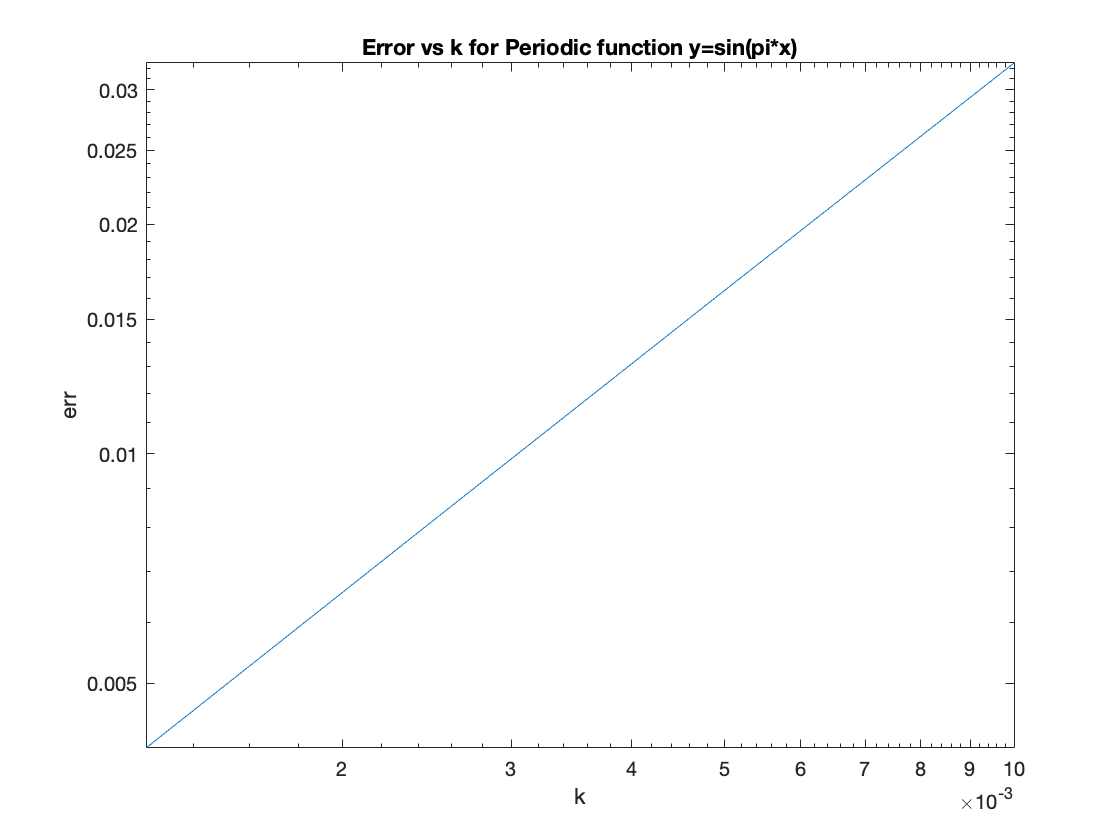

figure;
loglog(k_lst, err);
title("Error vs k for Periodic function y=sin(pi*x)")
xlabel("k");
ylabel("err");

err

err =     0.0325
    0.0164
    0.0082
    0.0041


figure;

ans = -1

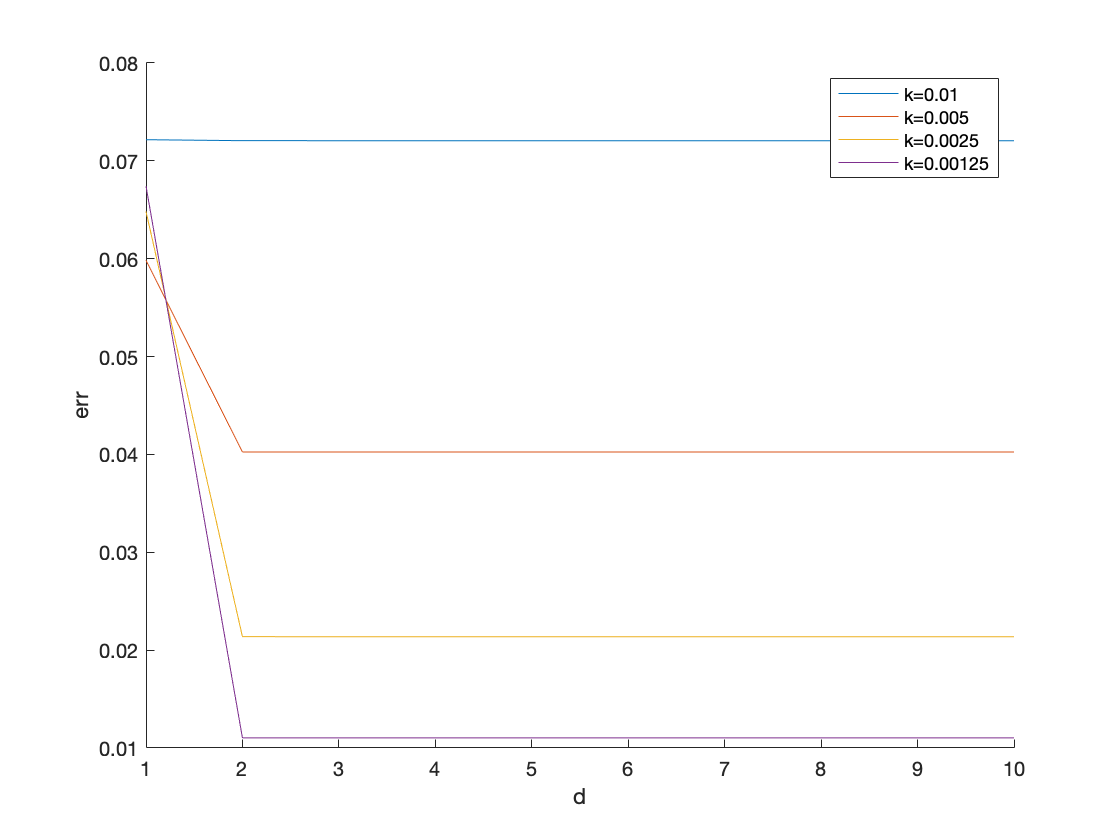

hold on;
loglog(d_lst, err')
xlabel("d")
ylabel("err")
legend('k=0.01', 'k=0.005', 'k=0.0025', 'k=0.00125')